# **Esercitzione n*3 - Stima modelli ingresso uscita**

## Descrizione del problema

E' stato condotto un esperimento per valutare la cinetica del C-peptide (un peptide secreto insieme all'insulina) in 7 soggetti misurando la risposta ad un bolo di C-peptide sintetico. L'esperimento prevede una misura al tempo 0 (prima del bolo) per determinare il valore della concentrazione basale. La misura effettuata al minuto 1 non e' da considerare (e deve essere trascurata nell'identificazione del modello) in quanto ci sono buone ragioni per affermare cha a quel tempo la concentrazione plasmatica non e' uniforme (la sostanza non si e' ancora distribuita nell'intero compartimento plasmatico - problemi di mescolamento). Le misure di concentrazione sono affette da un errore di misura caratterizzato da un CV del 4%. Come esercizio e in via esploratoria, identificare su i dati di almeno un soggetto i modelli a 1,2,3 esponenziali utilizzandp la tecnica dei minimi quadrati e dei minimi quadrati pesati (con peso pari all'inverso della varianza dell'errore di misura). 

clearvars;
clc;

## Lettura dei dati 

I dati sono relativi a 7 soggetti diversi e contenuti nei file` DatiCPSog1.dat`, `DatiCPSog2.dat, ecc.`

% Importazione dei dati 
d_sog1 = importdata("DatiCPsog1.dat");
d_sog2 = importdata("DatiCPsog2.dat");
d_sog3 = importdata("DatiCPsog3.dat");
d_sog4 = importdata("DatiCPsog4.dat");
d_sog5 = importdata("DatiCPsog5.dat");
d_sog6 = importdata("DatiCPsog6.dat");
d_sog7 = importdata("DatiCPsog7.dat");

Dal momento che i dati letti attraverso la funzione `importdata `sono organizzati in una struttura che richiederebbe molte operazioni, si memorizzano le informazioni in semplici array. Tale procedura consente di effettuare in agilita' le successive operazioni di data cleaning.

% Data retrieval
dose1 = str2num(d_sog1.textdata{1,2});
t1 = str2num(cell2mat(d_sog1.textdata(4:end,1)));
c1 = str2num(cell2mat(d_sog1.textdata(4:end,2)));

dose2 = str2num(d_sog2.textdata{1,2});
t2 = str2num(cell2mat(d_sog2.textdata(4:end,1)));
c2 = str2num(cell2mat(d_sog2.textdata(4:end,2)));

dose3 = str2num(d_sog3.textdata{1,2});
t3 = str2num(cell2mat(d_sog3.textdata(4:end,1)));
c3 = str2num(cell2mat(d_sog3.textdata(4:end,2)));

dose4 = str2num(d_sog4.textdata{1,2});
t4 = str2num(cell2mat(d_sog4.textdata(4:end,1)));
c4 = str2num(cell2mat(d_sog4.textdata(4:end,2)));

dose5 = str2num(d_sog5.textdata{1,2});
t5 = str2num(cell2mat(d_sog5.textdata(4:end,1)));
c5 = str2num(cell2mat(d_sog5.textdata(4:end,2)));

dose6 = str2num(d_sog6.textdata{1,2});
t6 = str2num(cell2mat(d_sog6.textdata(4:end,1)));
c6 = str2num(cell2mat(d_sog6.textdata(4:end,2)));

dose7 = str2num(d_sog7.textdata{1,2});
t7 = str2num(cell2mat(d_sog7.textdata(4:end,1)));
c7 = str2num(cell2mat(d_sog7.textdata(4:end,2)));


## Analisi visiva

Prima di effettuare il fitting dei possibili modelli a 1,2,3 esponenziali con i minimi quadrati o minimi quadrati pesati, si effettua un'analisi visiva dei dati relativi ai 7 soggetti dello studio. Il grafico riporta esattamente le misurazioni effettuate prima e dopo la somministrazione del bolo. La misura corrispondente al minuto 0 rappresenta la contrazione di C-peptide basale, mentre quelle successive sono relative all'effetto della somministrazione. Tuttavia ai fini del fitting dei diversi modelli, la misura dopo il primo minuto deve essere scartata poiche' la concentrazione plasmatica non e' uniforme. 

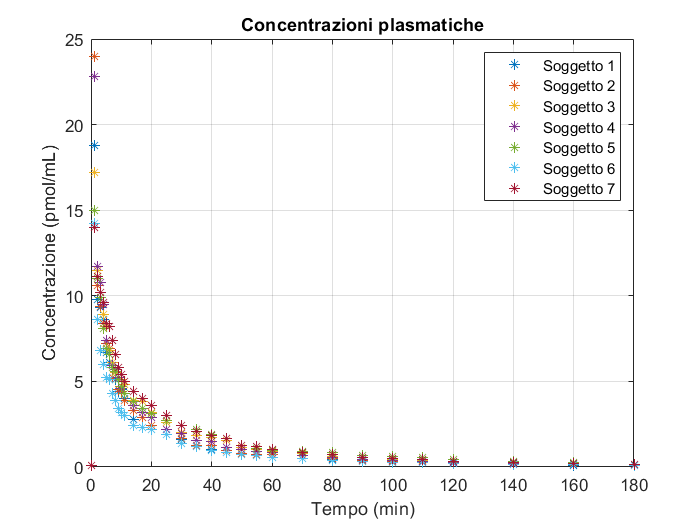

% Plot concentrazioni plasmatiche
plot(t1,c1,"*",t2,c2,"*",t3,c3,"*",t4,c4,"*",t5,c5,"*",t6,c6,"*",t7,c7,"*"),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Concentrazioni plasmatiche"), legend("Soggetto 1","Soggetto 2","Soggetto 3","Soggetto 4", ...
"Soggetto 5","Soggetto 6","Soggetto 7")

Eliminazione della concentrazione basale e delle misure non necessarie nel fitting.

c1 = c1 - c1(1); % Eliminazione concentrazione basale
c1 = c1(3:end);  % Eliminazione misura concentrazione basale e minuto successivo
t1 = t1(3:end);  % Eliminazione misura concentrazione basale e minuto successivo (tempo)
c2 = c2 - c2(1);
c2 = c2(3:end);
t2 = t2(3:end);
c3 = c3 - c3(1);
c3 = c3(3:end);
t3 = t3(3:end);
c4 = c4 - c4(1);
c4 = c4(3:end);
t4 = t4(3:end);
c5 = c5 - c5(1);
c5 = c5(3:end);
t5 = t5(3:end);
c6 = c6 - c6(1);
c6 = c6(3:end);
t6 = t6(3:end);
c7 = c7 - c7(1);
c7 = c7(3:end);
t7 = t7(3:end);

## Stima dei parametri con Minimi Quadrati (LS) e Minimi Quadrati Pesati (WLS)

Il metodo ai Minimi Quadrati (*Least Squares*) consente di trovere i parametri `p` del modello tali che la discrepanza tra i dati *z* e le predizioni del modello *h(ti,p)* sia minima. Per far questo si utilizza il seguente funzionale di costo: 


$$J\left(p\right)=\sum_{i=1}^N {\left(z_i -y_i \right)}^2 =\sum_{i=1}^N {\left(z_i -h\left(t_i \;,p\right)\right)}^2 =\sum_{i=1}^N {e_i }^2$$
 

Bisogna percio' risolvere il seguente problema di ottimizzazione:


$$\hat{p_{\mathrm{LS}} } =\mathrm{argmin}\left(J\left(p\right)\right)$$


In modo analogo si definisce il funzionale di costo per i Minimi Quadrati Pesati (*Weighted Least Squares*) considerando la matrice dei pesi *W = diag(w1,w2,...,wn)*:


$$J_W \left(p\right)={|\left|z-H\left(p\right)\right|\left|\right.}^2 =\sum_{i=1}^N {{w_i e}_i }^2 \;\left(p\right)$$


in cui l'errore *ei* ha peso differente sei i *wi *sono diversi tra loro. Ancora una volta e' necessario risolvere il seguente problema di ottimizzazione: 


$$\hat{p_{\mathrm{WLS}} } =\mathrm{argmin}\left(J_W \left(p\right)\right)\;$$


Quando la funzione h che determina l'uscita predetta dal modello non e' lineare, il problema non e' risolvibile in forma chiusa ed e' necessario ricorrere a metodi iterativi (in Matlab si usa la funzione `lsqnonlin`). 

## Fitting di modelli ingresso uscita a 1,2,3 esponenziali

Segue il fitting dei modelli ingresso uscita con Minimi Quadrati e Minimi Quadrati Pesati per uno specifico paziente.

selectedSogg = "Soggetto4"; % Selezione del soggetto 
switch selectedSogg
    case "Soggetto1"
        c = c1;
        t = t1;
    case "Soggetto2"
        c = c2;
        t = t2;
    case "Soggetto3"
        c = c3;
        t = t3;
    case "Soggetto4"
        c = c4;
        t = t4;
    case "Soggetto5"
        c = c5;
        t = t5;
    case "Soggetto6"
        c = c6;
        t = t6;
    case "Soggetto7"
        c = c7;
        t = t7;
end

### Fittining modello ingresso uscita mono-esponenziale con LS e WLS

p0 = [18.72,0.7];
options = optimoptions('lsqnonlin','Display','iter');
[x_ls,resnorm_ls,residual_ls,~,~,~,jacobian_ls] = lsqnonlin(@funzionale,p0,[],[],options,t,c,1);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         446.518                           201
     1          6         446.518             10            201      
     2          9         446.518            2.5            201      
     3         12         239.322          0.625       3.81e+03      
     4         15         47.5717           1.25            776      
     5         18         16.7429            2.5           24.2      
     6         21         13.7088        1.74881           54.3      
     7         24         13.4543       0.267562             13      
     8         27         13.4273       0.111387           4.68      
     9         30         13.4238      0.0393608           1.68      
    10         33         13.4234      0.0142625          0.609      
    11         36         13.4233     0.00518824          0.222      
    12         39         13.423

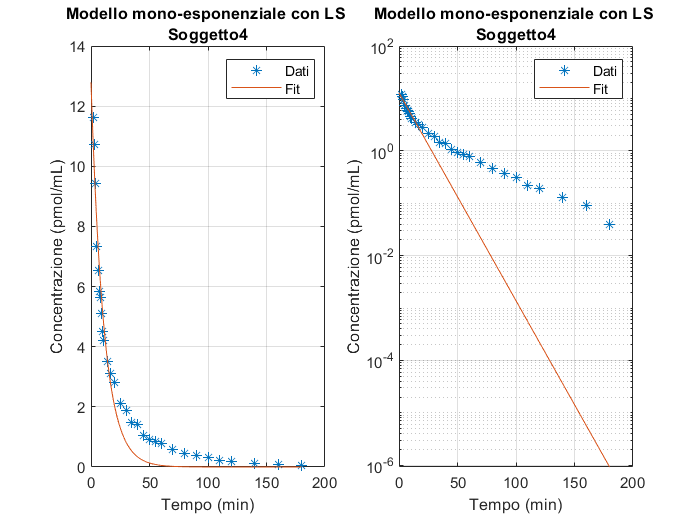

t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x_ls(1)*exp(-x_ls(2)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello mono-esponenziale con LS ",selectedSogg]), legend("Dati","Fit"); 

subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x_ls(1)*exp(-x_ls(2)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello mono-esponenziale con LS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 1-exp: A = ",num2str(x_ls(1))," alpha = ",num2str(x_ls(2))]); % Stampa dei parametri del fitting

    "Parametri LS 1-exp: A = "    "12.7914"    " alpha = "    "0.091351"

